# Image Compression

## Load the image

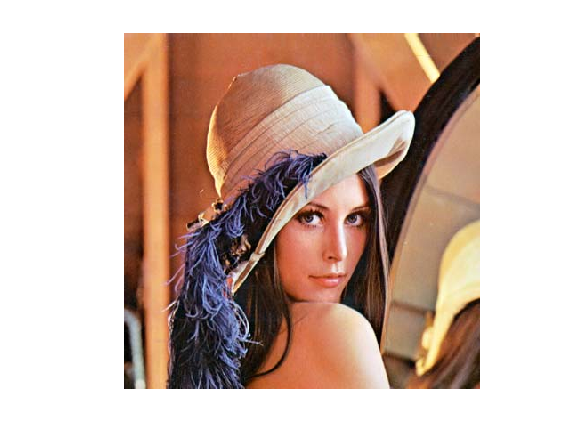

im = imread('lenna.jpg');
imshow(im);

## `Convert the image to grayscale`

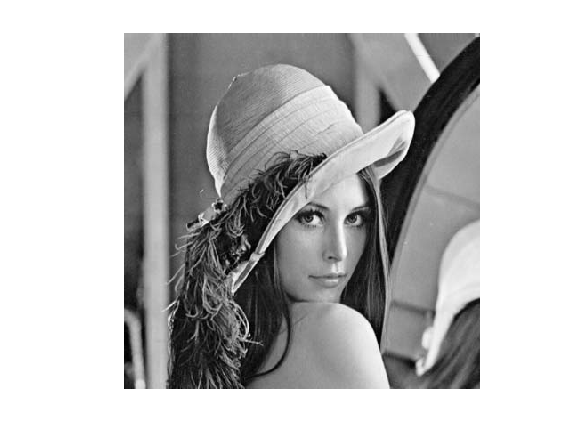

img = rgb2gray(im);
imshow(img);

## Divide the image into non-overlapping 8x8 blocks

row = size(img, 1);
col = size(img, 2);

images = zeros(row/8 * col/8, 8, 8);

for i=1:8:row
    for j=1:8:col
        indx = round(i/8)*floor(col/8) + floor(j/8 + 1);
        %display(indx);
        images(indx,:,:) = img(i:i+7,j:j+7);
    end
end

fprintf("%d %d %d\n",size(images));

2500 8 8


## Testing if splitting was right

check_img = zeros(row, col);
for k=1:size(images,1)
    j = (rem(k,col/8)-1)*8 + 1;
    if j < 0
        j = (floor(col/8) - 1) * 8 + 1;
    end
    i = floor((k-1)/(row/8))*8 +1;
    check_img(i:i+7, j:j+7) = images(k,:,:);
    %fprintf("%d %d %d\n", i, j, k);
end

imshow(check_img,[]);

## Compute the DCT (discrete cosine transform) of each block

images_dct = zeros(size(images,1),8,8);
for i=1:size(images,1)
    tim = zeros(8,8);
    tim(:,:) = images(i,:,:);
    images_dct(i,:,:) = floor(dct2(tim));
end


## Scaling all the dct co-efficients by a fixed number

quantize_scale = 64;
images_dct_scaled = floor(images_dct / quantize_scale);

## Getting the compressed image by inversing the dct and quantization

images_dct_scaled_back = images_dct_scaled * quantize_scale;

images_dct_reversed = reverse_dct(images_dct_scaled_back);

img_compressed = essemble_img(images_dct_reversed, row, col);

imshow(img_compressed,[]);

## Taking only top 8 dct co-efficient for compression

images_dct_top8 = zeros(size(images_dct));
for i=1:size(images_dct,1)
    tim = zeros(8,8);
    tim(:,:) = images_dct(i,:,:);
    [val, indx] = sort(tim(:) , 'descend');
    [r, c] = ind2sub(size(tim), indx(1:32));
    for k=1:size(r,1)
        images_dct_top8(i,r(k),c(k)) = val(k);
    end
    %display(images_dct_top8(i,:,:));
    %display(images_dct(i,:,:));
    %pause;
end

## compressing image

%images_dct_top8 = images_dct;
images_dct_reversed = reverse_dct(images_dct_top8);

img_compressed = essemble_img(images_dct_reversed, row, col);

imshow(img_compressed,[]);

## Compressing image using jpeg kernel

quantize_kernel = [16,11,10,16,24,40,51,61;...
    12,12,14,19,26,58,60,55;...
    14,13,16,24,40,57,69,56;...
    14,17,22,29,51,87,80,62;...
    18,22,37,56,68,109,103,77;...
    24,35,55,64,81,104,113,92;...
    49,64,78,87,103,121,120,101;...
    72,92,95,98,112,100,103,99;];


images_dct_kernelized = zeros(size(images_dct));
for i=1:size(images_dct,1)
    tim = zeros(8,8);
    tim(:,:) = images_dct(i,:,:);
    images_dct_kernelized(i,:,:) = floor(tim ./ quantize_kernel);
    %display(images_dct_top8(i,:,:));
    %display(images_dct(i,:,:));
    %pause;
end

## Compressing image

%images_dct_top8 = images_dct;
images_dct_reversed = reverse_dct(images_dct_kernelized);

img_compressed = essemble_img(images_dct_reversed, row, col);

imshow(img_compressed,[]);


## Converting the Red-Green-Blue image to a Lumina and Chroma one

img_yc = rgb2ycbcr(uint8(im));
imshow(img_yc,[])

## Compressing each channel by a constant factor

scale = 128;
img_yc_compressed = uint8(zeros(400,400,3));
img_yc_compressed(:,:,1) = floor(img_yc(:,:,1)/8) * 8;
img_yc_compressed(:,:,2) = floor(img_yc(:,:,2)/scale) * scale;
img_yc_compressed(:,:,3) = floor(img_yc(:,:,3)/scale) * scale;

%imshow(im, []);
imshow(ycbcr2rgb(img_yc_compressed), []);

test

img_compressed = compress_image(img, 'scale',2);
imshow(img_compressed,[]);

## Compress each channel by jpeg kernel

scale = 4;
img_yc_compressed = uint8(zeros(400,400,3));
img_yc_compressed(:,:,1) = compress_image(img_yc(:,:,1),'scale', 1);
img_yc_compressed(:,:,2) = compress_image(img_yc(:,:,2),'scale', scale);
img_yc_compressed(:,:,3) = compress_image(img_yc(:,:,3),'scale', scale);

%imshow(im, []);
imshow(ycbcr2rgb(img_yc_compressed), []);

## Compress by Fast Fourier Transform

scale = 16;
img_yc_compressed = uint8(zeros(400,400,3));
img_yc_compressed(:,:,1) = compress_image(img_yc(:,:,1),'scale', 1, 'transform', 'fft');
img_yc_compressed(:,:,2) = compress_image(img_yc(:,:,2),'scale', scale, 'transform', 'fft');
img_yc_compressed(:,:,3) = compress_image(img_yc(:,:,3),'scale', scale, 'transform', 'fft');

%imshow(im, []);
imshow(ycbcr2rgb(img_yc_compressed), []);


## Image histogram

figure();
imhist(img);
title('Image histogram for lenna.jpg');


## Predictive Loss less compression

pred_err = floor(prediction_error(img));
imhist(pred_err);

edges = unique(pred_err);
cnts = histc(pred_err(:),edges);
sz = row * col;
prob_dist = cnts ./ sz;

dict = myhuffmandict(num2cell(double(edges')), prob_dist');
comp = huffmanenco_(pred_err(:), dict);

Error using huffmanenco_ (line 83)
The Huffman dictionary provided does not have the codes for all the input signals.